% #1592
% Find the area of the shape
syms x;
y=4*x-x^2

$$y = 4\,x-x^{2}$$

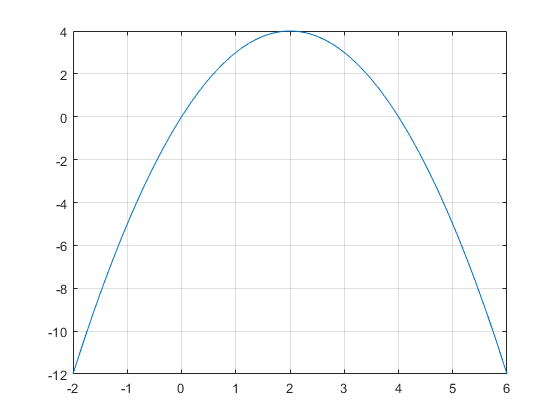

fplot(y,[-2,6]);
grid

sx=solve(y,x)

$$sx = \left(\begin{array}{c} 0\\ 4 \end{array}\right)$$

% 0,4
S=int(y,x,sx(1),sx(2))

$$S = \frac{32}{3}$$

% 32/3

% #1593
% Find the area of a figure bounded by a parabola
syms x y real;
f1=y-(x-1)^2;
f2=x^2-y^2/2-1

$$f2 = x^{2}-\frac{y^{2}}{2}-1$$

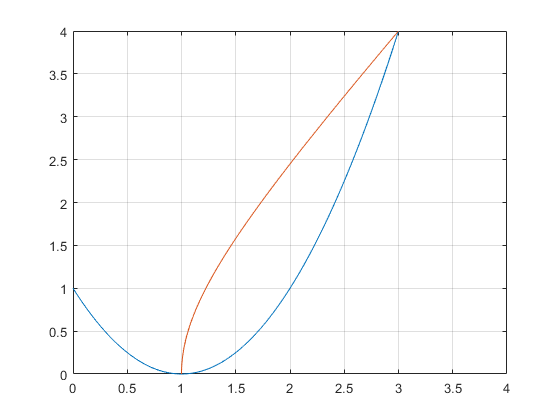

digits(3)

fimplicit(f1,[0,4])
hold on
fimplicit(f2,[0,4])
grid on
hold off


slv=solve(y==(x-1)^2,x^2-y^2/2==1)

slv = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]



A=slv.x(1)

$$A = 1$$

B=slv.x(2)

$$B = 3$$

% x^2-y^2/2=1 => y=sqrt(2*(x^2-1))
y1=sqrt(2*(x^2-1))

$$y1 = \sqrt{2}\,\sqrt{x^{2}-1}$$

y2=(x-1)^2

$$y2 = {\left(x-1\right)}^{2}$$

S=int(y1-y2,x,1,3)

$$S = \sqrt{2}\,\log\left(\sqrt{2}-1\right)+\frac{10}{3}$$

% 2^(1/2)*log(2^(1/2) - 1) + 10/3 - ?
vpa(S)

$$ans = 2.09$$

% 2.09 - ?

% #1594
% Calculate the area of a figure bounded by one arch of a cycloid
% S = int (t1-t2) y(t)*diff(x(t)) dt 
syms t;
x=2*(t-sin(t))

$$x = 2\,t-2\,\sin\left(t\right)$$

y=2*(1-cos(t))

$$y = 2-2\,\cos\left(t\right)$$

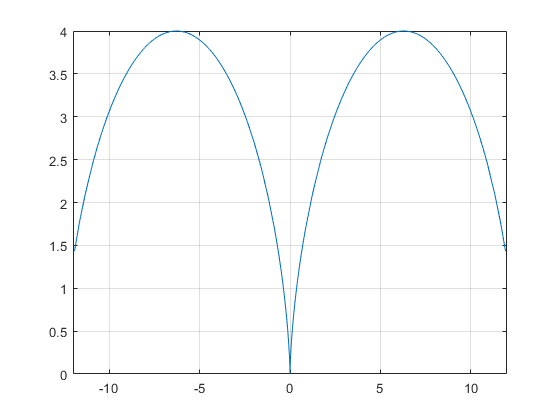

fplot(x,y)
grid on

dx=diff(x)

$$dx = 2-2\,\cos\left(t\right)$$

% 2 - 2*cos(t)
S=int(y*dx,t,0,2*pi)

$$S = 12\,\pi$$

% 12*pi

% $1595
% Calculate the area of a figure bounded by a lemiscate
syms theta;
% ro^2=2*cos(2*theta)

% S=1/2* int (alpha-beta) ro^2 d_theta
S=4*1/2*int(2*cos(2*theta),theta,0,pi/4)

$$S = 2$$

% 2

% #1596
% Calculate the area of a figure bounded by given lines
% y=-x^2, x+y+2=0
syms x y;
f1=-x^2

$$f1 = -x^{2}$$

f2=-x-2

$$f2 = -x-2$$

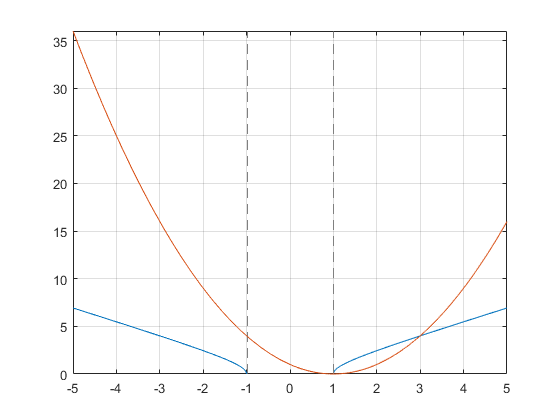

fplot(y1)
hold on
fplot(y2)
grid on
hold off

slv=solve(y==-x^2,x+y+2==0)

slv = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


slv.x

$$ans = \left(\begin{array}{c} -1\\ 2 \end{array}\right)$$

% 2,-1

% S = int (a-b) (f2(x)-f1(x)) dx
S=int(f1-f2,x,-1,2)

$$S = \frac{9}{2}$$

% 9/2

% #1597
syms x y;
y1=16/x^2

$$y1 = \frac{16}{x^{2}}$$

y2=17-x^2

$$y2 = 17-x^{2}$$

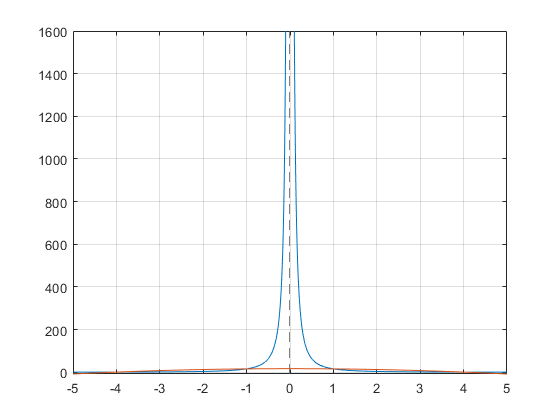

fplot(y1)
hold on
fplot(y2)
grid on
hold off


slv=solve(y==16/x^2,y==17-x^2)

slv = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


slv.x

$$ans = \left(\begin{array}{c} -4\\ 4\\ -1\\ 1 \end{array}\right)$$

% 4 -4 1 -1

% S = int (a-b) (f2(x)-f1(x)) dx
S=int(y2-y1,x,1,4)

$$S = 18$$

% 18

% #1598
syms x y;
y1=sqrt(4*x^3)

$$y1 = 2\,\sqrt{x^{3}}$$

y2=2*x^2

$$y2 = 2\,x^{2}$$

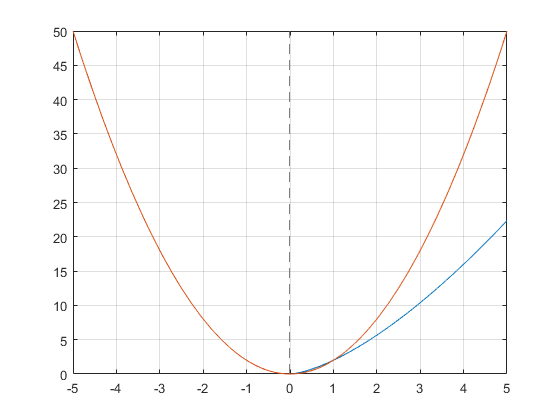

fplot(y1)
hold on
fplot(y2)
grid on
hold off


slv=solve(y^2==4*x^3,y==2*x^2)

slv = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


slv.x

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

% 0 1

% S = int (a-b) (y2-y1) dx
S=int(y1-y2,x,0,1)

$$S = \frac{2}{15}$$

% 2/15

% #1599
syms x y;
f1(x,y)=x*y-20

$$f1(x, y) = x\,y-20$$

f2(x,y)=x^2+y^2-41

$$f2(x, y) = x^{2}+y^{2}-41$$

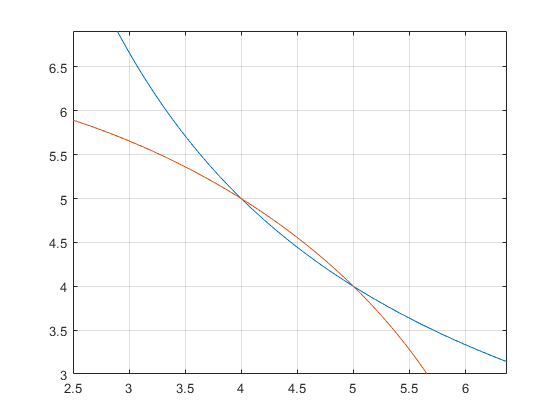

digits(3)

fimplicit(f1)
hold on
fimplicit(f2)
grid on
hold off

xlim([2.50 6.37])
ylim([3.00 6.91])


slv=solve(x*y==20,x^2+y^2==41)

slv = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


slv.x

$$ans = \left(\begin{array}{c} -4\\ -5\\ 5\\ 4 \end{array}\right)$$


% ys=sqrt(41-x^2)-20/x
y1=20/x

$$y1 = \frac{20}{x}$$

y2=sqrt(41-x^2)

$$y2 = \sqrt{41-x^{2}}$$

S=int(y2-y1,x,4,5)

$$S = \frac{41\,\mathrm{asin}\left(\frac{5\,\sqrt{41}}{41}\right)}{2}-\frac{41\,\mathrm{asin}\left(\frac{4\,\sqrt{41}}{41}\right)}{2}-20\,\log\left(\frac{5}{4}\right)$$

S=simplify(S)

$$S = \frac{41\,\mathrm{asin}\left(\frac{5\,\sqrt{41}}{41}\right)}{2}-\frac{41\,\mathrm{asin}\left(\frac{4\,\sqrt{41}}{41}\right)}{2}-20\,\log\left(\frac{5}{4}\right)$$

pretty(S)

    / 5 sqrt(41) \          / 4 sqrt(41) \
asin| ---------- | 41   asin| ---------- | 41
    \     41     /          \     41     /            / 5 \
--------------------- - --------------------- - 20 log| - |
          2                       2                   \ 4 /



vpa(S)

$$ans = 0.0741$$

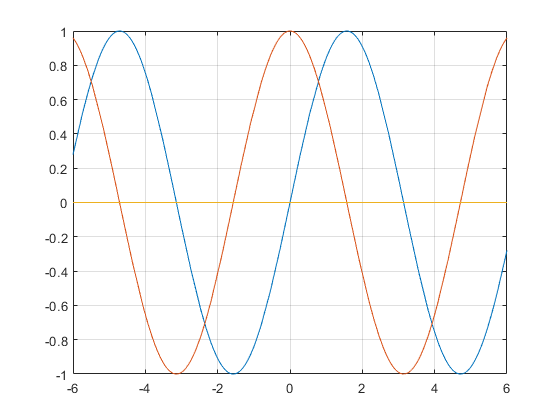

% #1600
clear;
syms x;
y1=sin(x);
y2=cos(x);
x=0;

fplot(y1)
hold on
fplot(y2)
plot([-6 6],[0 0])
grid on
hold on


syms x y;
slv1=solve(y==cos(x),y==sin(x))

slv1 = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


slv1.x

$$ans = \left(\begin{array}{c} \frac{\pi }{4}\\ -\frac{3\,\pi }{4} \end{array}\right)$$


S=int(y2-y1,x,0,pi/4)

$$S = \sqrt{2}-1$$

% 2^(1/2) - 1